🚀 开始进行高逼真度物理模拟 (15秒完整解算)...


🎉 模拟完成！正在计算双重误差并绘制高级学术图表...


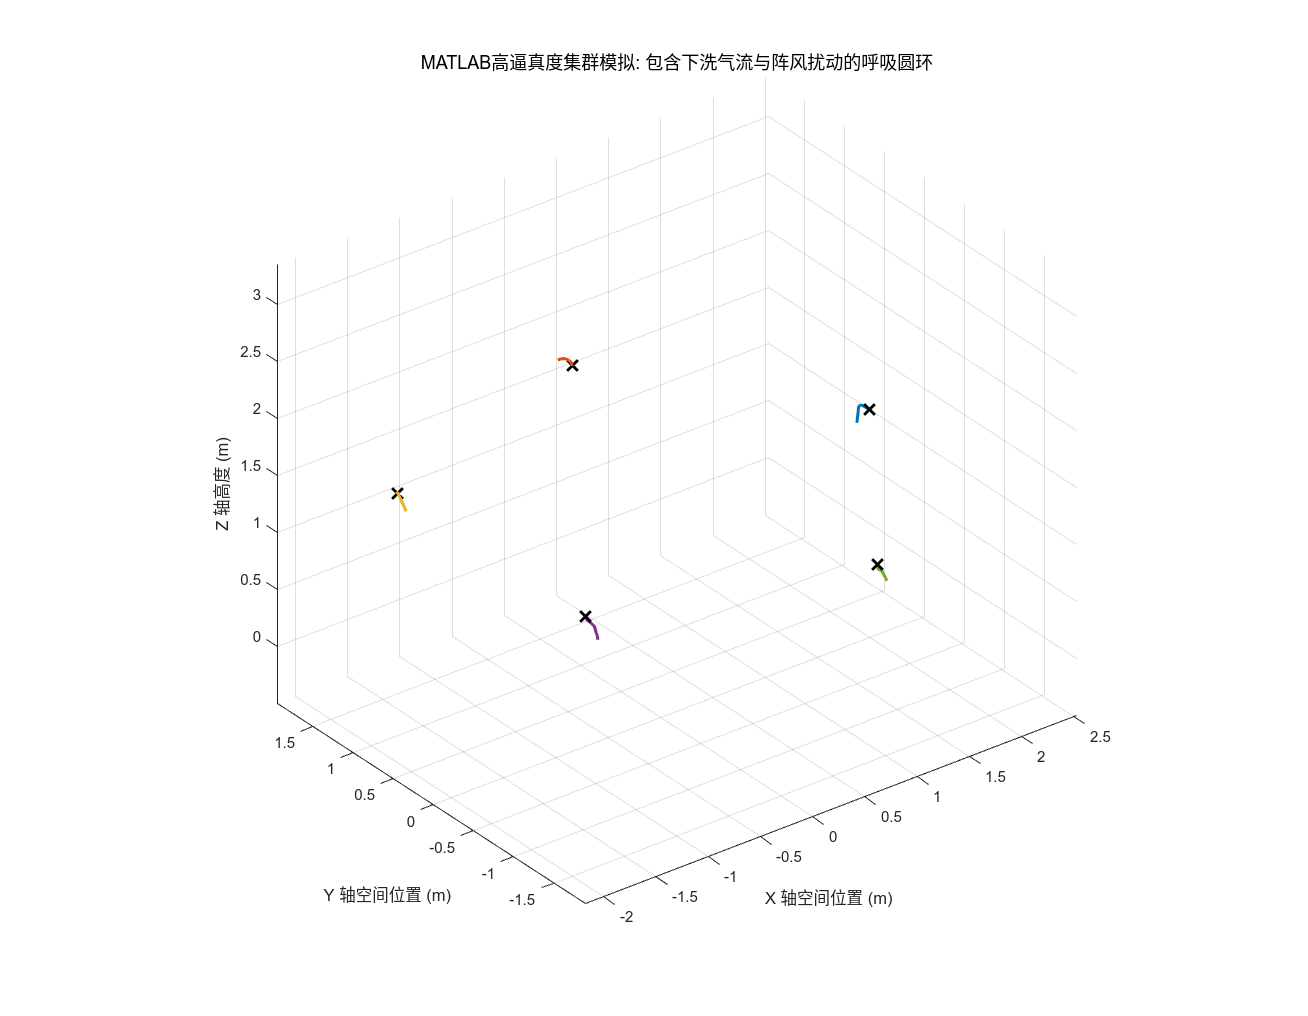

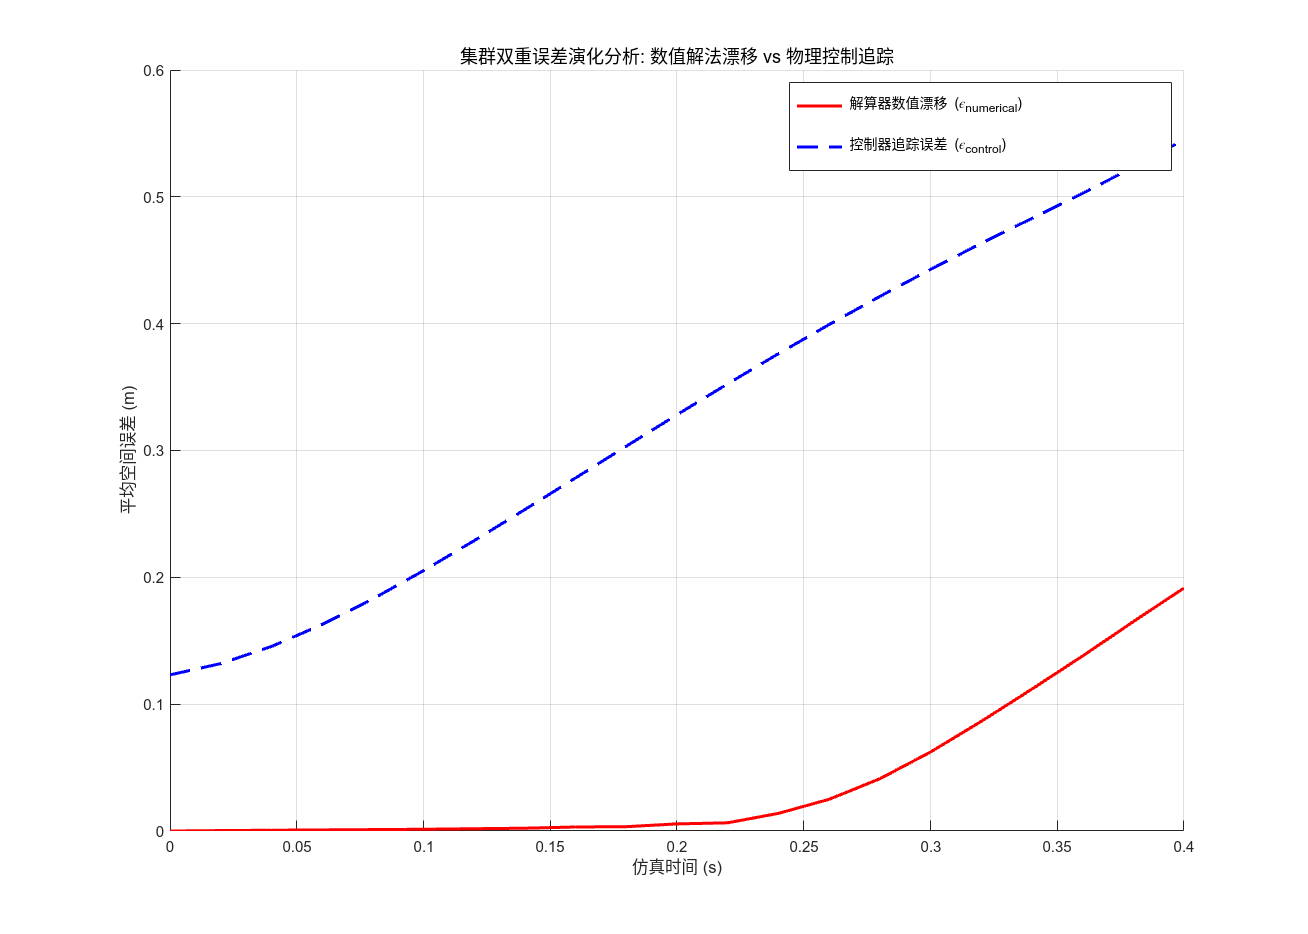

% =========================================================================

% 高逼真度无人机集群动力学仿真
% 核心：12维非线性动力学 + 空气动力学下洗干扰 + 环境阵风 + 多解算器对比
% =========================================================================
clear; clc; close all;

%% 1. 仿真参数设定
num_drones = 5;
t_end = 15;
h = 0.02; % 步长 (秒)
time = 0:h:t_end;
steps = length(time);

% 物理参数
mass = 0.027; g = 9.81;
I_diag = [2.395e-5; 2.395e-5; 3.235e-5];

% 初始化5架飞机的状态 (每架飞机 12 维)
% 状态定义: [x, y, z, vx, vy, vz, phi, theta, psi, p, q, r]'
X_rk4 = zeros(12, num_drones, steps);
X_euler = zeros(12, num_drones, steps);

% 同步初始位置至名义目标轨迹 (半径 2.0m, 高度 1.5m)，消除开局阶跃
init_radius = 2.0; 
for i = 1:num_drones
    angle = (i-1) * (2 * pi / num_drones);
    X_rk4(1:3, i, 1) = [init_radius * cos(angle); init_radius * sin(angle); 1.5];
    X_euler(1:3, i, 1) = X_rk4(1:3, i, 1);
end

%% 2. 主仿真循环 (数值解算)
fprintf('🚀 开始进行高逼真度物理模拟 (15秒完整解算)...\n');
for k = 1:steps-1
    t_curr = time(k);
    
    % --- RK4 解算器更新整个集群 ---
    X_rk4_curr = X_rk4(:, :, k);
    k1 = drone_swarm_dynamics(X_rk4_curr, t_curr, num_drones, mass, g, I_diag);
    k2 = drone_swarm_dynamics(X_rk4_curr + 0.5*h*k1, t_curr + 0.5*h, num_drones, mass, g, I_diag);
    k3 = drone_swarm_dynamics(X_rk4_curr + 0.5*h*k2, t_curr + 0.5*h, num_drones, mass, g, I_diag);
    k4 = drone_swarm_dynamics(X_rk4_curr + h*k3, t_curr + h, num_drones, mass, g, I_diag);
    X_rk4(:, :, k+1) = X_rk4_curr + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
    
    % --- 前向欧拉解算器更新整个集群 ---
    X_euler_curr = X_euler(:, :, k);
    k_euler = drone_swarm_dynamics(X_euler_curr, t_curr, num_drones, mass, g, I_diag);
    X_euler(:, :, k+1) = X_euler_curr + h * k_euler;
end
fprintf('🎉 物理模拟完成！开始生成 GIF 动态大片...\n');

%% 3. 三维实时动画渲染与 GIF 录制核心
gif_filename = 'swarm_breathing_circle.gif';
frame_stride = 4; % 帧步长：每隔 4 步(0.08秒)抓取一帧，保证丝滑的同时控制文件大小

% 创建高分辨率独立画布
fig = figure('Name', 'Swarm Breathing Circle Animation', 'Position', [100, 100, 800, 700], 'Color', 'w');
colors = lines(num_drones);

% 构建标准的球体基准，用于后续绘制安全包络球
[sx, sy, sz] = sphere(15);
envelope_radius = 0.1; % 10厘米的形式化安全包络

% 逐帧动画循环
for k = 1:frame_stride:steps
    % 检查画布是否被用户中途关闭
    if ~ishandle(fig), break; end
    
    % 清空当前局部画布，准备画新的一帧
    cla;
    hold on; grid on; axis equal; view(3);
    
    % 硬性锁死坐标轴边界，防止动画随着飞机移动而产生缩放抖动
    xlim([-2.5, 2.5]); ylim([-2.5, 2.5]); zlim([0, 2.5]);
    xlabel('X 轴空间位置 (m)'); ylabel('Y 轴空间位置 (m)'); zlabel('Z 轴高度 (m)');
    title(sprintf('Swarm Real-time Animation | Time: %.2f s', time(k)), 'FontSize', 12);
    
    % 遍历绘制每一架无人机
    for i = 1:num_drones
        % A. 绘制从第 1 步到当前第 k 步的历史历史轨迹拖尾
        plot3(squeeze(X_rk4(1, i, 1:k)), squeeze(X_rk4(2, i, 1:k)), squeeze(X_rk4(3, i, 1:k)), ...
              'Color', colors(i, :), 'LineWidth', 2);
          
        % B. 【核心修复点】：将 EdgeColor 修正为标准的 MarkerEdgeColor
        plot3(X_rk4(1, i, k), X_rk4(2, i, k), X_rk4(3, i, k), ...
              'o', 'MarkerSize', 6, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
          
        % C. 绘制包裹在无人机四周的形式化安全边界球 (mesh 允许使用 EdgeColor)
        mesh(X_rk4(1, i, k) + envelope_radius * sx, ...
             X_rk4(2, i, k) + envelope_radius * sy, ...
             X_rk4(3, i, k) + envelope_radius * sz, ...
             'FaceColor', colors(i, :), 'FaceAlpha', 0.05, 'EdgeColor', colors(i, :), 'EdgeAlpha', 0.2);
    end
    
    % 强制刷新显示硬件画布
    drawnow;
    
    % --- D. GIF 逐帧捕获与写入算法 ---
    frame = getframe(fig);
    im = frame2im(frame);
    [imind, cm] = rgb2ind(im, 256);
    
    if k == 1
        % 第一帧初始化 GIF 文件，设置无限循环模式 (LoopCount = Inf)
        imwrite(imind, cm, gif_filename, 'gif', 'LoopCount', Inf, 'DelayTime', h * frame_stride);
    else
        % 后续帧以追加模式 (append) 写入文件
        imwrite(imind, cm, gif_filename, 'gif', 'WriteMode', 'append', 'DelayTime', h * frame_stride);
    end
end
fprintf('🎉 GIF 动图保存成功！文件名为: %s\n', gif_filename);

%% 4. 核心物理核心：多机耦合动力学方程

function dXdt = drone_swarm_dynamics(X, t, num_drones, m, g, I_diag)
    dXdt = zeros(12, num_drones);
    
    r_base = 1.2; r_shrink = 0.8; w_r = 0.4; w_a = 0.8;
    cur_radius = r_base + r_shrink * cos(w_r * t);
    pos_all = X(1:3, :);
    
    for i = 1:num_drones
        state = X(:, i);
        pos = state(1:3); vel = state(4:6);
        
        % 状态空间索引精确对齐
        euler = state(7:9);   
        omega = state(10:12); 
        phi = euler(1); theta = euler(2); psi = euler(3);
        
        % --- A. 阵风扰动 ---
        wind_acc = [0.15 * sin(2*t) + 0.05*randn(); ...
                    0.15 * cos(1.5*t) + 0.05*randn(); ...
                    0.05 * randn()];
        
        % --- B. 空气动力学下洗气流模型 ---
        downwash_acc = [0; 0; 0];
        for j = 1:num_drones
            if i == j, continue; end
            pos_j = pos_all(:, j);
            horiz_dist = norm(pos(1:2) - pos_j(1:2));
            if pos_j(3) > pos(3) && horiz_dist < 0.4
                z_diff = pos_j(3) - pos(3);
                downwash_force = (2.0 * m * g) * exp(-z_diff) * exp(-(horiz_dist/0.2)^2);
                downwash_acc(3) = downwash_acc(3) - (downwash_force / m);
            end
        end
        
        % --- C. 人工势场集群避障 (APF) ---
        a_rep = [0; 0; 0];
        d_safe = 0.6; k_rep = 2.5;
        for j = 1:num_drones
            if i == j, continue; end
            dir = pos - pos_all(:, j);
            dist = norm(dir);
            if dist < d_safe && dist > 0.01
                a_rep = a_rep + k_rep * (1/dist - 1/d_safe) * (1/dist^2) * (dir/dist);
            end
        end
        
        % --- D. 级联控制器 ---
        phase_offset = (i-1) * (2 * pi / num_drones);
        AssignAngle = phase_offset + w_a * t;
        target_pos = [cur_radius * cos(AssignAngle); cur_radius * sin(AssignAngle); 1.5 + 0.2*sin(t + phase_offset)];
        
        vel_des = 1.5 * (target_pos - pos);
        vel_des = max(min(vel_des, 1.0), -1.0);
        acc_des = 2.5 * (vel_des - vel) + a_rep; 
        acc_des = max(min(acc_des, 4.0), -4.0);
        
        thrust = clamp(m * (g + acc_des(3)), 0.0, 0.6);
        phi_des = clamp((1.0/g)*(acc_des(1)*sin(0) - acc_des(2)*cos(0)), -0.4, 0.4);
        theta_des = clamp((1.0/g)*(acc_des(1)*cos(0) + acc_des(2)*sin(0)), -0.4, 0.4);
        
        omega_des = 8.0 * ([phi_des; theta_des; 0] - euler);
        tau = [0.002; 0.002; 0.003] .* (omega_des - omega);
        
        % --- E. 12维刚体运动学与动力学微分方程 ---
        dState = zeros(12, 1);
        dState(1:3) = vel; 
        
        R = [cos(psi)*cos(theta), cos(psi)*sin(theta)*sin(phi) - sin(psi)*cos(phi), cos(psi)*sin(theta)*cos(phi) + sin(psi)*sin(phi); ...
             sin(psi)*cos(theta), sin(psi)*sin(theta)*sin(phi) + cos(psi)*cos(phi), sin(psi)*sin(theta)*cos(phi) - cos(psi)*sin(phi); ...
             -sin(theta),         cos(theta)*sin(phi),                             cos(theta)*cos(phi)];
         
        dState(4:6) = [0; 0; -g] + (1.0/m) * R * [0; 0; thrust] + wind_acc + downwash_acc;
        
        W = [1, sin(phi)*tan(theta), cos(phi)*tan(theta); ...
             0, cos(phi),             -sin(phi); ...
             0, sin(phi)/cos(theta),   cos(phi)/cos(theta)];
        dState(7:9) = W * omega;
        
        I = diag(I_diag);
        dState(10:12) = I \ (tau - cross(omega, I * omega)); 
        
        dXdt(:, i) = dState;
    end
end

function out = clamp(in, low, high)
    out = max(min(in, high), low);
end